### Systemic Arteries Model (triangle wave for Qao)

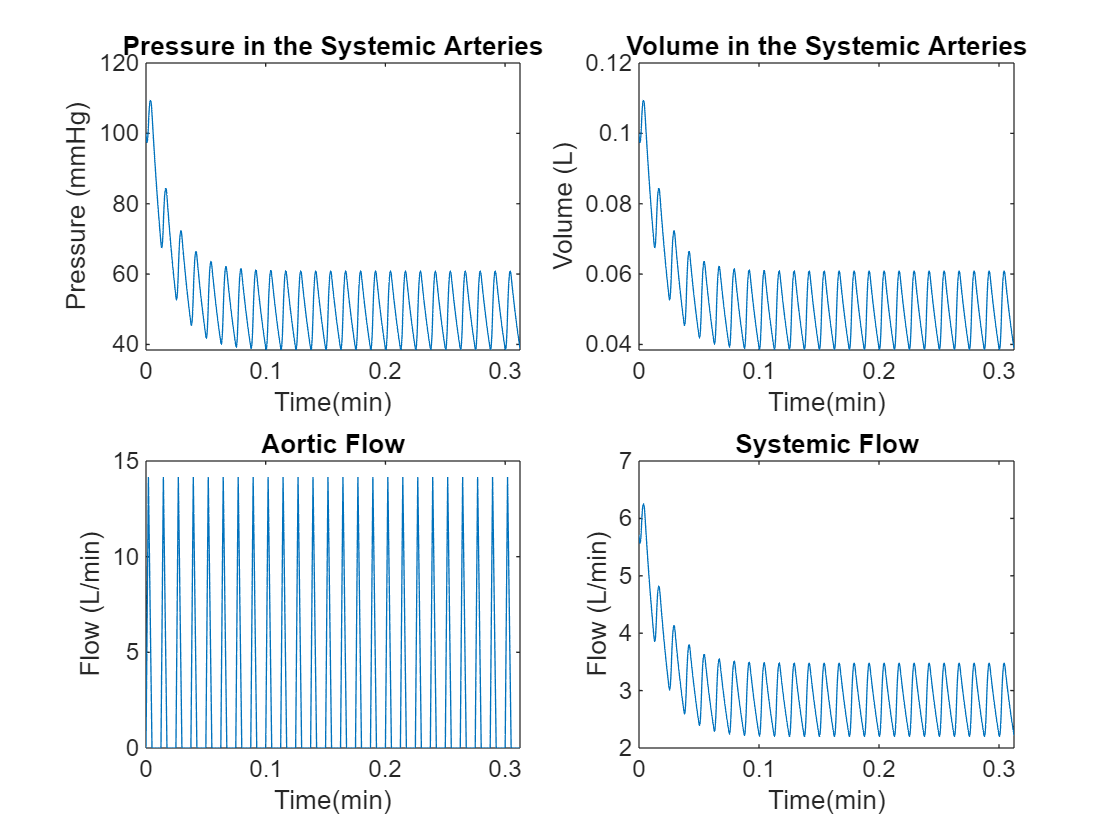

clear;clc;close all 

function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

%Initial Parameters
Psa=100; % Initial Condition for pressure in systemic arteries  (mmHg) 
Rs=17.5; % Resistance of the systemic circuit (mmHg/(L/min)) 
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
Qmax=14.14;      
% Max flow rate through aorta during systole (L/min) 
Csa=0.001; % Compliance constant for systemic arteries (L/mmHg) 
% Csa was fiddled with to achieve Psa of 120/80 mmHg 
dt=0.0001;        
% Time step (min) 
t=0:dt:25*T;  % Vectorized time (min) 
%% Solve Diff Eq 
for k=1:length(t)-1  % Go from beginning of time to end 
    QAo(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Flow rate at any given point in time 
    Psa(k+1)=Psa(k)+dt*(QAo(k)-Psa(k)/Rs)/Csa;  % Pressure at any given point in time 
end 
% Systemic Flow (Qs)
Qs=Psa/Rs;
% Volume in Systemic Arteries
Vsa=Csa*Psa;

% Plotting
subplot(2,2,1);
plot(t,Psa);
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');
subplot(2,2,2);
plot(t,Vsa);
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');
subplot(2,2,3);
plot(t(1:end-1),QAo); 
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');
subplot(2,2,4);
plot(t,Qs); 
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

### Left Heart Model

clear;clc;close all 

% Hemodynamics: dynamic heart compliance

function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left
% ventricle during systole and diastole, respectively. CLVS, CRVS,
% CLVD, and CRVD.
% Remainder of cardiac cycle

tc=rem(t,T);
for ii=1:length(tc) % For every time point that’s in tc
    if tc(ii)<ts % If tc is less than ts, systole
        e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
        CV(ii)=CVD*(CVS/CVD)^e;
    else % If tc is greater than ts, diastole
        e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
        CV(ii)=CVS*(CVD/CVS)^e;
    end
end
end

% WE NEED TO MODEL THE VALVES FIRST

### VALVES

% State of valves -> open (1) or closed (0)

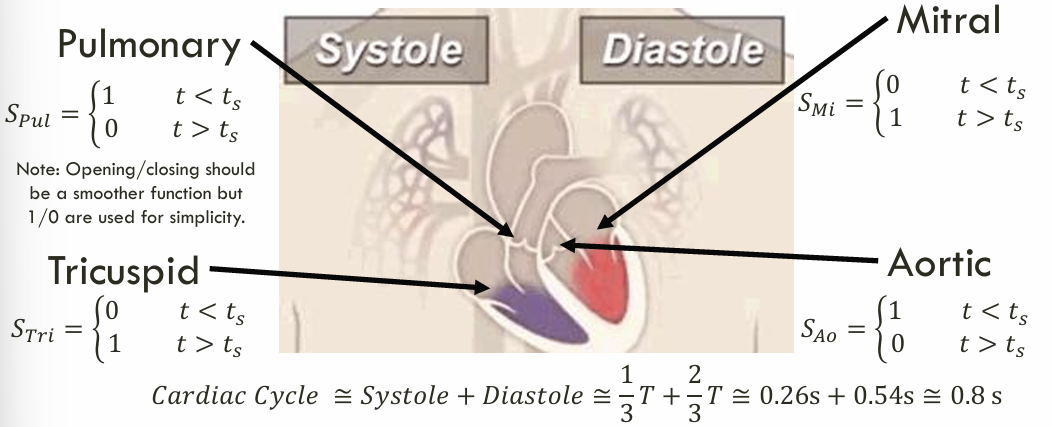

% Systole -> AO + PUL open, MI + TRI closed
% Diastole -> AO + PUL closed, MI + TRI open